# Understanding Rotations

## Setup the environment

clear all
close all
W = eye(4)

W =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


B = rpy2r(0.4,0.5,0.3)

B =     0.8384   -0.0938    0.5369
    0.2593    0.9351   -0.2415
   -0.4794    0.3417    0.8083


B = r2t(B)

B =     0.8384   -0.0938    0.5369         0
    0.2593    0.9351   -0.2415         0
   -0.4794    0.3417    0.8083         0
         0         0         0    1.0000


## Plotting the Reference Frames

Plotting the Wordl Reference Frame {W}

trplot(W, 'frame','W','text_opts',{'FontSize', 14},'arrow','color', 'b','thick',1,...
          'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5],'width', 1,'length',1.2 )
hold on

Plotting the reference frame {B}

trplot(B, 'frame','B','text_opts', {'FontSize', 14},'arrow','color', 'r','thick',1,...
           'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5])
hold on       

A convenient view

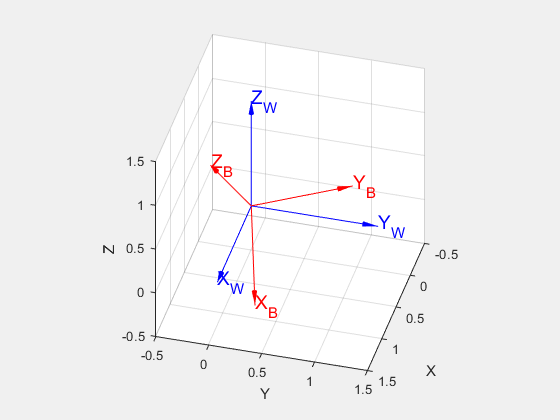

view(105,37)

## Rotating sequence

It is well know (from Euler angles) that you can get any attitude by rotating in sequence (6 for XYZ..ZYX) and (6 for XYX..ZYZ). 

In this example the vector to aligned is the Z of {eR} doing 1 rotx + 2 roty + 3 rotz

V=B(1:3,2) % z component of eR Frame

V =    -0.0938
    0.9351
    0.3417


Exten the axes lines of frame {A} to see more clear the eR components

Extend_WRF_axis()

Drawing the components of Z eR in {W} Reference Frame

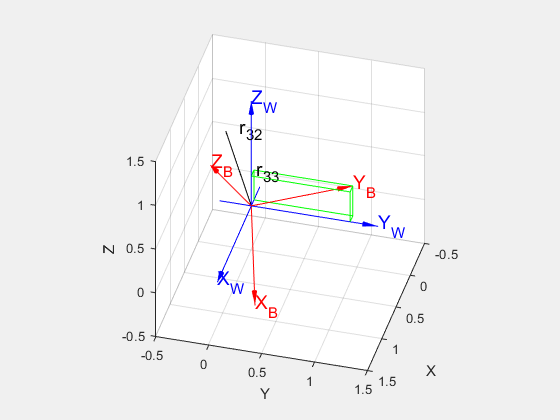

Components_Z()

Computing the needed rotation to recover horizontality (z's aligned) 

th_z=atan2(V(1),V(2))

th_z = -0.1000


B1=trotz(th_z)*B 

B1 =     0.8601    0.0000    0.5101         0
    0.1743    0.9398   -0.2939         0
   -0.4794    0.3417    0.8083         0
         0         0         0    1.0000


See the first animation

tranimate(B,B1,20,'frame','B1','text_opts', {'FontSize', 14},'arrow','color', 'black','thick',4,...
          'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5])

th_x=atan2(B1(3,2),B1(2,2)) 

th_x = 0.3488

B2=trotx(-th_x)*B1

B2 =     0.8601    0.0000    0.5101         0
         0    1.0000    0.0000         0
   -0.5101   -0.0000    0.8601         0
         0         0         0    1.0000


tranimate(B1,B2,20,'frame','B2','text_opts', {'FontSize', 14},'arrow','color', 'black', [0 1 0],'thick',4,...
          'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5],'length',1.3)


th_y=atan2(B2(3,1),B2(1,1))

th_y = -0.5353

B3=troty(th_y)*B2

B3 =     1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000         0
    0.0000   -0.0000    1.0000         0
         0         0         0    1.0000


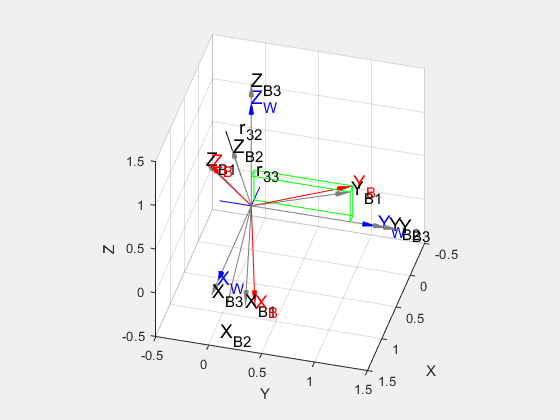

tranimate(B2,B3,20,'frame','B3','text_opts', {'FontSize', 14},'arrow','color', 'black', [0 1 0],'thick',4,...
          'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5],'length',1.4)